# Lab 5: RLC Circuit Frequency Response 

f = [0.101, 1.497, 2.488, 2.53, 2.629, 2.728, 4.023, 8.065, 20.04, 100.5]; % actual frequency
w = f * 1000 * 2 * pi; % actual omega
v_s = [5.03, 4.88, 4.88, 4.84, 4.84, 4.84, 4.29, 4.84, 4.8, 4.8]; % input voltage
v_o = [0.0243, 0.424, 2.24, 2.31, 2.44, 2.31, 0.832, 0.238, 0.084, 0.0166]; % output voltage
G_exp = v_o ./ v_s; % gain caluclation
GdB_exp = 20 .* log10(G_exp); % gain in dB
delta_T = [0.00016, 0.000018, 0.000014, 0, -0.000026, -0.000056, -0.000031, -0.0000128, -0.00000256]; % delta T
calc_phase = delta_T .* f(2:end) .* 1000 .* 360; % calculate phase
Phase_exp = [90, calc_phase]; % phase (deg)

C_nom = 2.2 * 10^-6; R = 220; L = 1.2 * 10^-3; % constants
w_r_nom = 1/sqrt(L*C_nom); % calculate nominal resonant frequnecy (rad/s)
w_r_exp = 16.518*10^3; % experimental resonant frequnecy (rad/s)
C_exp = 1/(w_r_exp^2*L); % calculate expiremental capacitance 

s = tf('s'); % Declare s as Laplace variable
TrFn = (s/(C_exp*R))/(s^2+s/(R*C_exp)+1/(L*C_exp)); % Create transfer function
[mag, ang] = bode(TrFn, w); % Evaluate magnitude and phase of transfer function for the frequencies in w. Returns mag in V/V and phase in degrees
G_sim = squeeze(mag); % Extract values from array mag
GdB_sim = 20*log10(G_sim); % simulated gain in dB
Phase_sim = squeeze(ang); % simulated phase in degrees

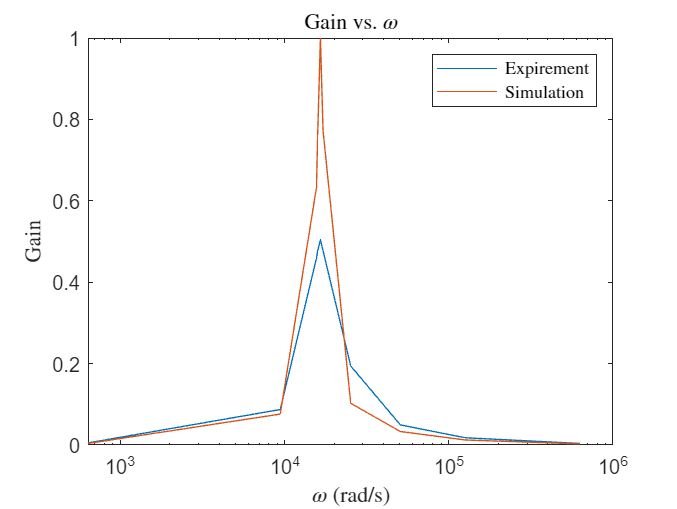

% plot gain vs. omega
figure(1); clf
semilogx(w, G_exp);
hold on
semilogx(w, G_sim);
hold off
title("Gain vs. $\omega$", "Interpreter", "latex")
xlabel("$\omega$ (rad/s)", "Interpreter", "latex")
ylabel("Gain", "Interpreter", "latex")
legend("Expirement", "Simulation", "Interpreter", "latex")

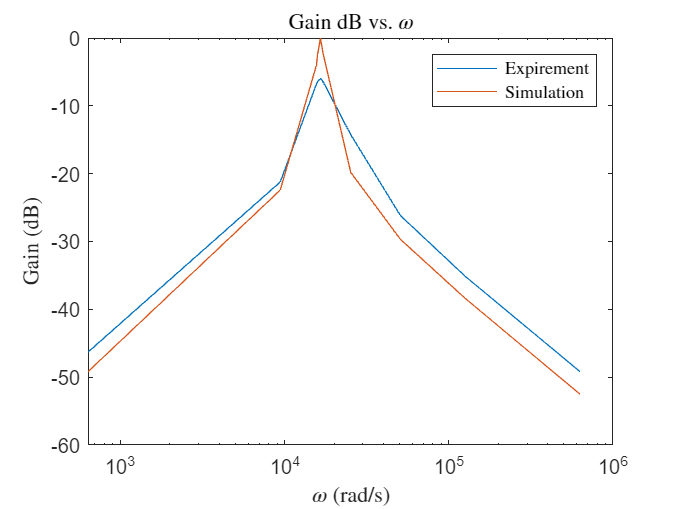


% plot gain (dB) vs. omega
semilogx(w, GdB_exp)
hold on 
semilogx(w, GdB_sim)
hold off
title("Gain dB vs. $\omega$", "Interpreter", "latex")
xlabel("$\omega$ (rad/s)", "Interpreter", "latex")
ylabel("Gain (dB)", "Interpreter", "latex")
legend("Expirement", "Simulation", "Interpreter", "latex")

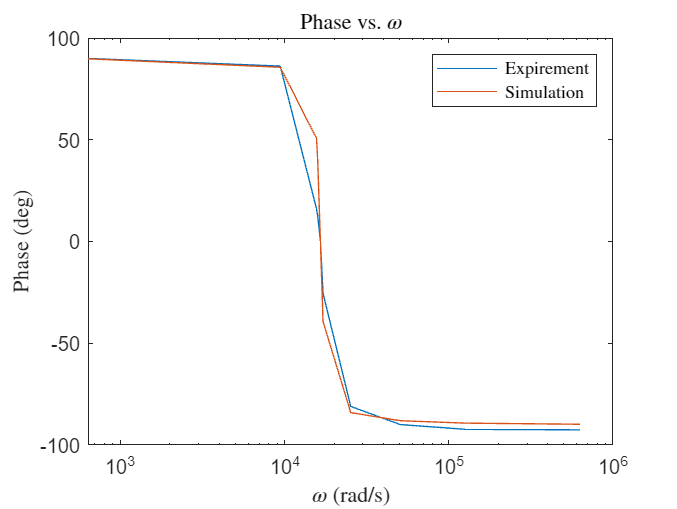


% plot phase (deg) vs. omega
semilogx(w, Phase_exp)
hold on 
semilogx(w, Phase_sim)
hold off
title("Phase vs. $\omega$", "Interpreter", "latex")
xlabel("$\omega$ (rad/s)", "Interpreter", "latex")
ylabel("Phase (deg)", "Interpreter", "latex")
legend("Expirement", "Simulation", "Interpreter", "latex")